cityStrings = ["Berlin", "Paris", "Rome", "Tokyo", "TestSet"];
city = cityStrings(1)

city = "Berlin"

popularity = false

popularity = logical
   0


price = false

price = logical
   0


visiting_time = false

visiting_time = logical
   0



destSights = getCityDataSet(city);
eta = getCityEta(city);
costs = getCityCosts(city);

% ST:  Algorithm Parameter Optimization
% For variable and param explanation please visit TSP_ACO
%    VARIABLE PARAMS     %

maxAnalyticsIts = 1001;
analyticsIts = 1;
Q = 1; %Q IS A CONSTANT

%q_0 = 0.18; % best range 0.12 - 0.21
numAnts = 25; % best range > 54
%Currently tracking beta
beta = 0; %approx. new best at 0.01; 0.01; WHY IS THAT??????????
gamma = 0;
alpha = 1 - beta - gamma;
maxIts = 200; %approx. new best at 950; 820;
rho = 0.43; %approx. new best at 0.22; 0.35; 0.48; 0.43

paramScores = zeros([1, 100]);
paramValues = zeros([1, 100]);
%Smaller array to avg the ten iterations per 
avgScores = zeros([1, 10]);
avgCount = 1;

while analyticsIts < maxAnalyticsIts

    %Change the parameter by a small value every tenth iteration
    if(mod(analyticsIts, 10) == 0)
        scoreAvg = sum(avgScores) / length(avgScores)
        paramScores(analyticsIts / 10) = scoreAvg;
        paramValues(analyticsIts / 10) = beta;

        avgScores = zeros([1, 10]);
        avgCount = 1;

        beta = beta + .1
    end

    %Set param in the analytic matrix for this iteration
    %paramScores(1,analyticsIts) = numAnts;


    params = struct('numAnts', numAnts, 'beta', beta, 'Q', Q, 'rho', rho);

    tau = ones(length(destSights),length(destSights));
    bestPath = 1:length(destSights);
    bestScore = newScorePath(0, bestPath, destSights, eta);

    numIts = 1;
    scores = zeros(1, maxIts);

    while numIts < maxIts
	    for ant_k = 1:numAnts
		    
		    path = zeros(1, length(destSights));
		    currInd = 1;
		    path(currInd) = randi(length(destSights));
		    unvisited = 1:length(destSights);
		    unvisited(path(1)) = [];
		    
		    for currInd = 1:(length(destSights) - 1)
			    r = path(currInd);

			    %if (rand < q_0)
				    %[~, sInd] = max(tau(r, unvisited) .* (1.0 ./ eta(r, unvisited)).^beta .* (1.0 ./ costs(r, unvisited)).^gamma);
				    %s = unvisited(sInd);
			    %else
				    vec = (tau(r, unvisited).^alpha) .* ((1.0 ./ eta(r, unvisited)).^beta) .* ((1.0 ./ costs(r, unvisited)).^gamma);
				    probs = vec ./ sum(vec);

				    if any(isnan(probs))
					    sInd = 1;
                    else
					    sInd = find(cumsum(probs) > rand, 1);
				    end
				    s = unvisited(sInd);
			    %end

			    path(currInd + 1) =  s;
			    unvisited(sInd) = [];
		    end
		    
		    score = newScorePath(0, path, destSights, eta);
		    if (score < bestScore)
			    bestScore = score;
			    bestPath = path;
		    end

            %ST: this circshift is used to use the same index in the following
            %for loop
		    toCities = circshift(path, [0,1]);
		    for ind = 1:length(destSights)
			    fromCity = path(ind);
			    toCity = toCities(ind);
                %ST: Better scores raise the pheromone concentration on the
                %edges the ant has traveled
			    tau(fromCity, toCity) = tau(fromCity, toCity) + Q / score;
		    end
        end
	    scores(numIts) = bestScore;
        %ST: The pheromone evaporation is done seperately here:
	    tau = (1 - rho) * tau;
	    numIts = numIts + 1;
    end

    disp("Best Score: " + bestScore);
    avgScores(avgCount) = bestScore;
    avgCount = avgCount + 1;
    analyticsIts = analyticsIts + 1;

end

Best Score: 111
Best Score: 122
Best Score: 119
Best Score: 109
Best Score: 120
Best Score: 114
Best Score: 116
Best Score: 117
Best Score: 114


scoreAvg = 104.2000

beta = 0.1000

Best Score: 116
Best Score: 113
Best Score: 116
Best Score: 110
Best Score: 106
Best Score: 112
Best Score: 109
Best Score: 112
Best Score: 113
Best Score: 116


scoreAvg = 112.3000

beta = 0.2000

Best Score: 107
Best Score: 110
Best Score: 111
Best Score: 109
Best Score: 109
Best Score: 114
Best Score: 104
Best Score: 111
Best Score: 109
Best Score: 112


scoreAvg = 109.6000

beta = 0.3000

Best Score: 106
Best Score: 109
Best Score: 106
Best Score: 106
Best Score: 108
Best Score: 106
Best Score: 112
Best Score: 106
Best Score: 108
Best Score: 112


scoreAvg = 107.9000

beta = 0.4000

Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 104
Best Score: 107
Best Score: 110
Best Score: 103
Best Score: 103
Best Score: 108
Best Score: 103


scoreAvg = 105

beta = 0.5000

Best Score: 103
Best Score: 103
Best Score: 106
Best Score: 106
Best Score: 103
Best Score: 106
Best Score: 107
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 104.3000

beta = 0.6000

Best Score: 104
Best Score: 106
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 104
Best Score: 106
Best Score: 103
Best Score: 103


scoreAvg = 103.8000

beta = 0.7000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 106
Best Score: 103
Best Score: 104
Best Score: 103
Best Score: 104
Best Score: 103
Best Score: 106


scoreAvg = 103.8000

beta = 0.8000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 105
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103.2000

beta = 0.9000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 1.0000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 1.1000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 1.2000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 1.3000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 1.4000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 1.5000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 1.6000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 1.7000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 1.8000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 1.9000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 2.0000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 2.1000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 2.2000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 2.3000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 2.4000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 2.5000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 2.6000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 2.7000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 2.8000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 2.9000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 3.0000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 3.1000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 3.2000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 3.3000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 3.4000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 3.5000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 3.6000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 3.7000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 3.8000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 3.9000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 4.0000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 4.1000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 4.2000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 4.3000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 4.4000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 4.5000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 4.6000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 4.7000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 4.8000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 4.9000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 5.0000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 5.1000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 5.2000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 5.3000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 5.4000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 5.5000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 5.6000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 5.7000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 5.8000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 5.9000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 6.0000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 6.1000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 6.2000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 6.3000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 6.4000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 6.5000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 6.6000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 6.7000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 6.8000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 6.9000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 7.0000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 7.1000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 7.2000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 7.3000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 7.4000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 7.5000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 7.6000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 7.7000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 7.8000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 7.9000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 8.0000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 8.1000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 8.2000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 8.3000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 8.4000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 8.5000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 8.6000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 8.7000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 8.8000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 8.9000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 9.0000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 9.1000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 9.2000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 9.3000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 9.4000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 9.5000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 9.6000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 9.7000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 9.8000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 9.9000

Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103
Best Score: 103


scoreAvg = 103

beta = 10.0000

Best Score: 103


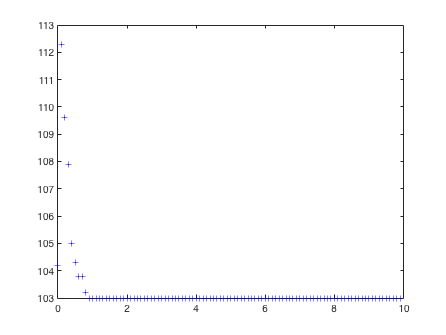


figure(1);
plot(paramValues,paramScores, 'b+');